# Project

# Taha Abedini

# 400101572

# 2.    Electroencephalography (EEG)

# 2.1 What is EEG?

The letter of the electrode stands for the general brain region that the electrode covers. From front to back, the electrode letter labeling is as follows: Fp (pre-frontal or frontal pole), F (frontal), C (central line of the brain), T (temporal), P (parietal), and O (occipital). Electrodes lying between these lines combine multiple letters, ordered from front to back. This applies to the higher-density systems, which is further explained in the next section. In addition, the letters M and A are sometimes used to refer to the mastoids or earlobes respectively. Typically, these locations are included to serve as a (offline) reference for signal analysis .

# 2.3 Frequency Bands of EEG

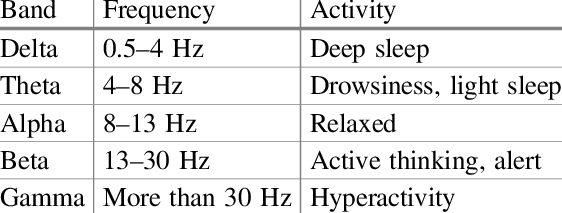

- EEG bands with their activity.

# 2.4 Sampling frequency

Nyquist criterion :


$$\omega_s =\frac{2\pi }{T}>2\omega_m =4\pi f_m \;\;\;\;\;;$$


Delta : $f_m =4\;\mathrm{Hz}\;\;\;\Longrightarrow \;\;\;T_s <\frac{2}{f_m }=500\mathrm{ms}\;$

Thate :$f_m =8\;\mathrm{Hz}\;\;\;\Longrightarrow \;\;T_s =\frac{2}{f_m }=250\;\mathrm{ms}\;$

Alpha :$f_m =13\;\mathrm{Hz}\;\;\;\Longrightarrow \;\;T_s =\frac{2}{f_m }\approx 154\;\mathrm{ms}\;\;$

Beta :$f_m =30\;\mathrm{Hz}\;\;\;\Longrightarrow \;\;T_s =\frac{2}{f_m }\approx 67\;\mathrm{ms}$

Gama :$f_m =100\;\mathrm{Hz}\;\;\;\Longrightarrow \;\;T_s =\frac{2}{f_m }=2\;\mathrm{ms}$   (consedring 100 Hz as a maximum frequency for brain) ;

# 3.     EEG Signal Processing (Subject 1)

## 3.3

We are going to import the dataset (Subject 1) to EEGLAB . We need code to import data :

clear ;
load('Subject1.mat');
load('AD.mat') ;
load('EEG1.mat') ;

subject1array1 = table2array(subject1);

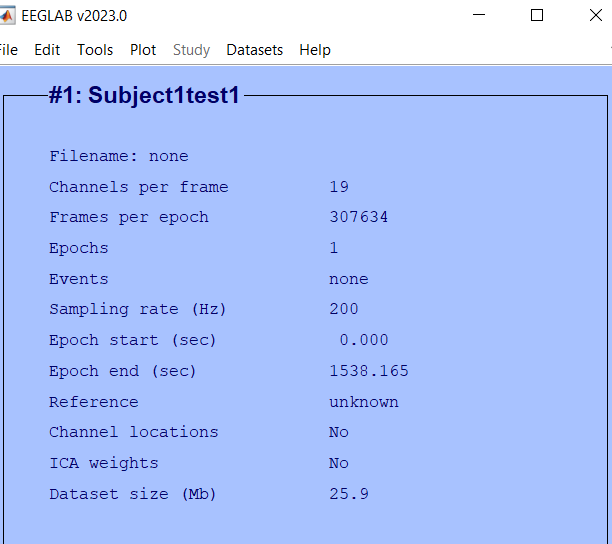

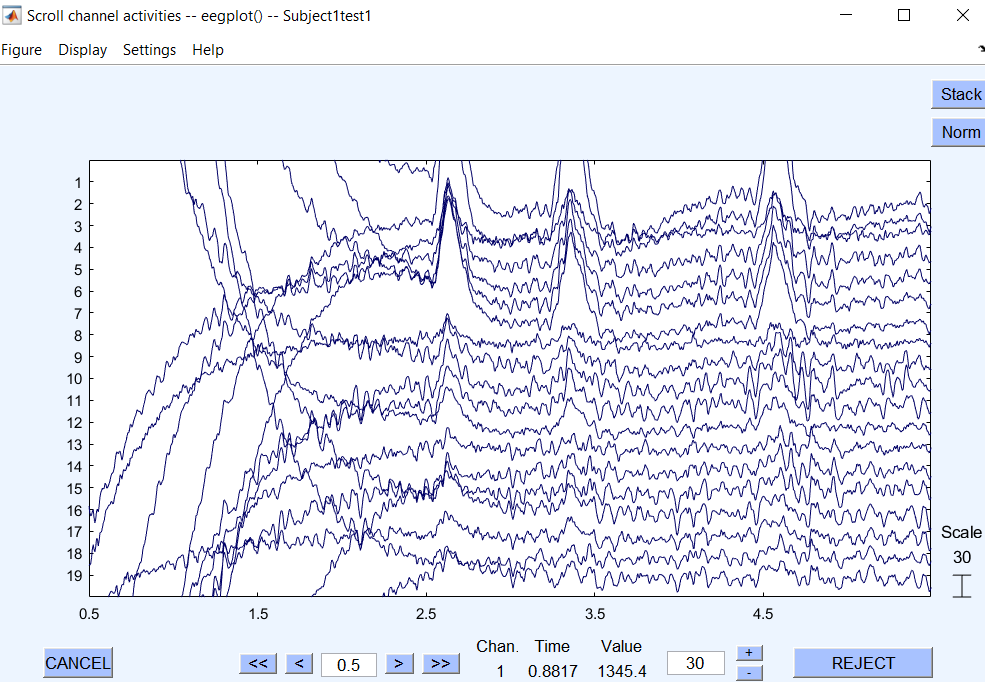

do Step 1 :

re-referencing data to the mean of the channels and use a bandpass filter to filter 0.5 - 40.5 Hz frequencies 

Also find frequency spectrum of Fz channel .

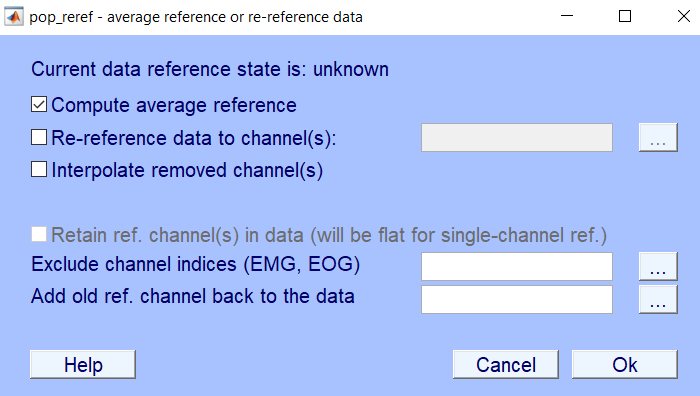

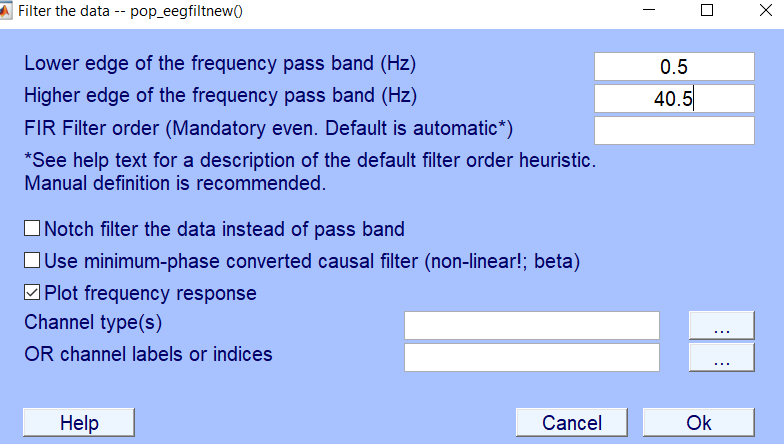

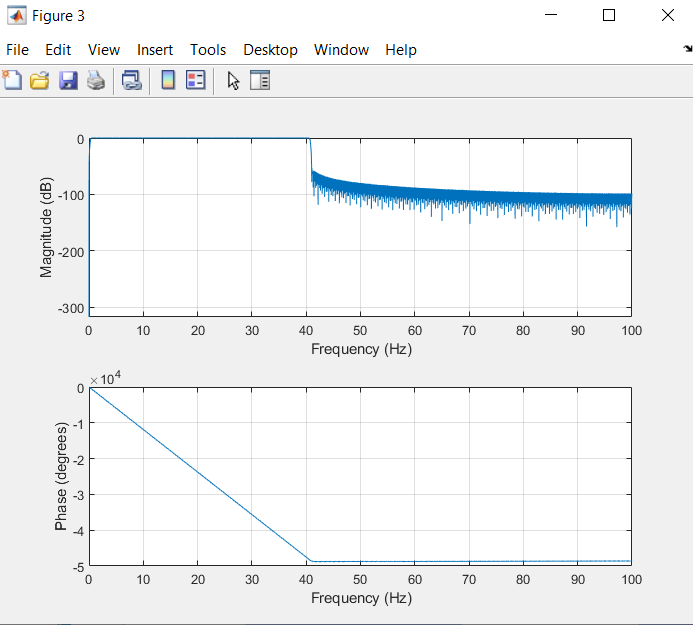

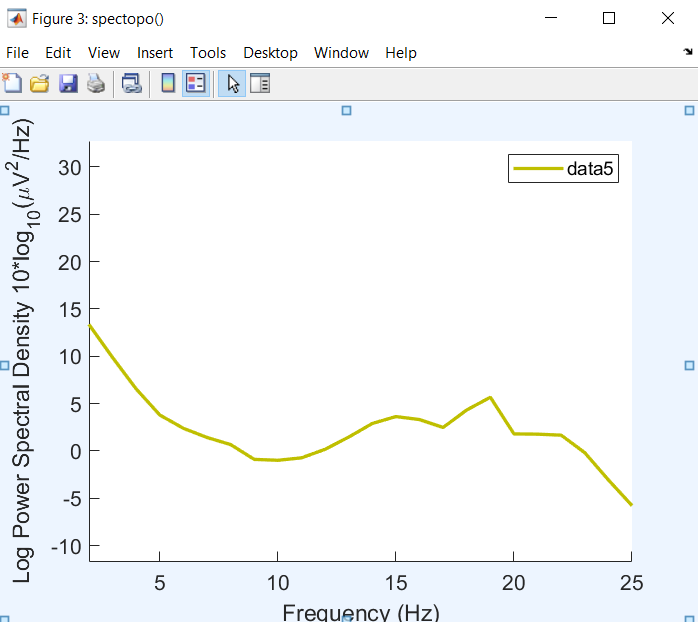

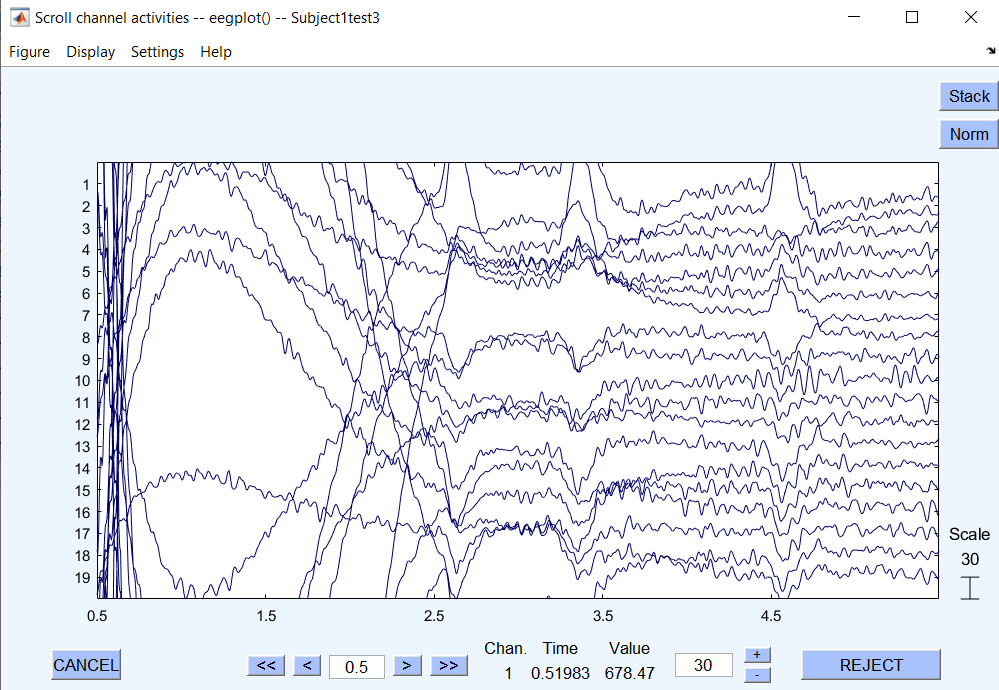

### do Step 2  :

removing artifacts and non-brain components

First of all we dont need data before 14s , so we are going to delete it .

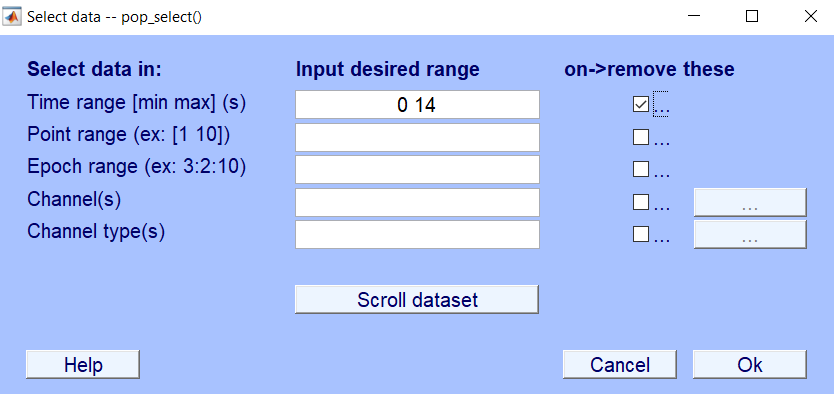

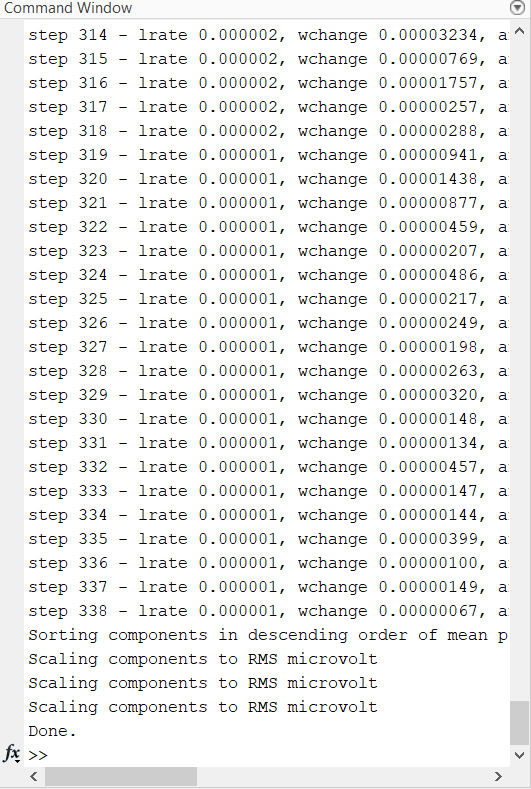

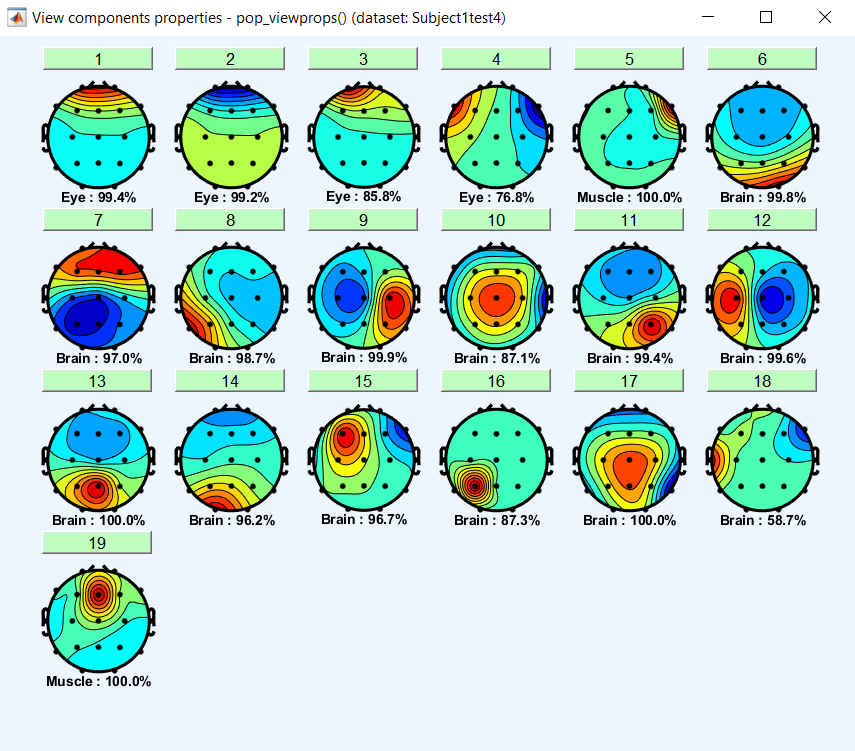

Now we are going to remove non-brain components :

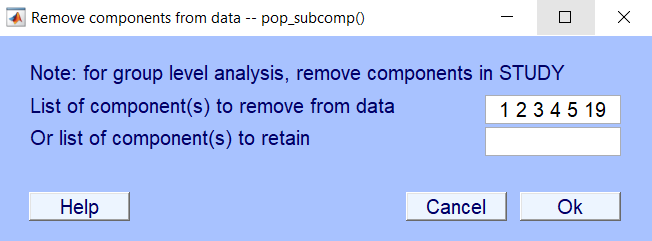

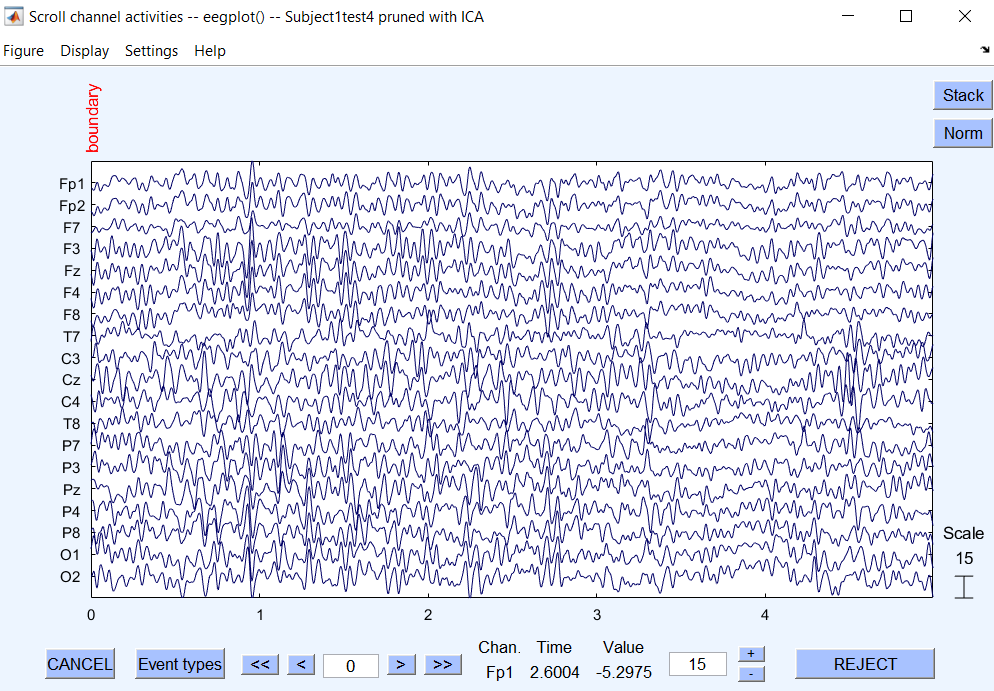

### do Step 3  :

Epoch the data of each subject.

We are going to define a function and use to epoch the data .

Also we have removed data befor 14s .

ep = epoch((EEG.data)'); %% function code is in functions part

#### do Step 4 :

removing noisy trial is our next step .

We are going to use the code in the project file .

noisy_trials1 = [] ;

for i = 1:19

    vr = sum ( nanstd (ep(i,:,:) ,[] ,2) .^2 ,2) ;
    noisy = find ( abs ( zscore ( vr )) > 3.5) ;
    noisy_trials1 = [noisy_trials1,noisy'] ;

end

noisy_trials1 = unique(noisy_trials1) ;

#### do Step 5 :

subsampling and creating struct .

fepoch = ep ( [1,5,10,15] , : , : ) ;

s1 = struct( 'epoch', {fepoch} , 'odor' , {AD(12).odor} , 'niosy' , {noisy_trials1} ) ;

# 3.     EEG Signal Processing (Subject 2)

clear ;

load('Subject2.mat');
load('Normal.mat') ;
load('EEG2.mat') ;

subject1array2 = table2array(subject2);

#### do Step 1 :

re-referencing data to the mean of the channels and use a bandpass filter to filter 0.5 - 40.5 Hz frequencies 

Also find frequency spectrum of Fz channel .

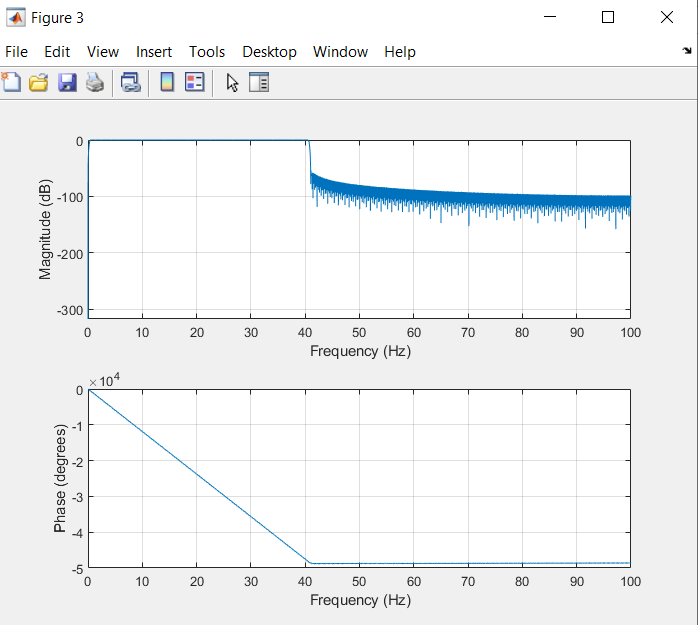

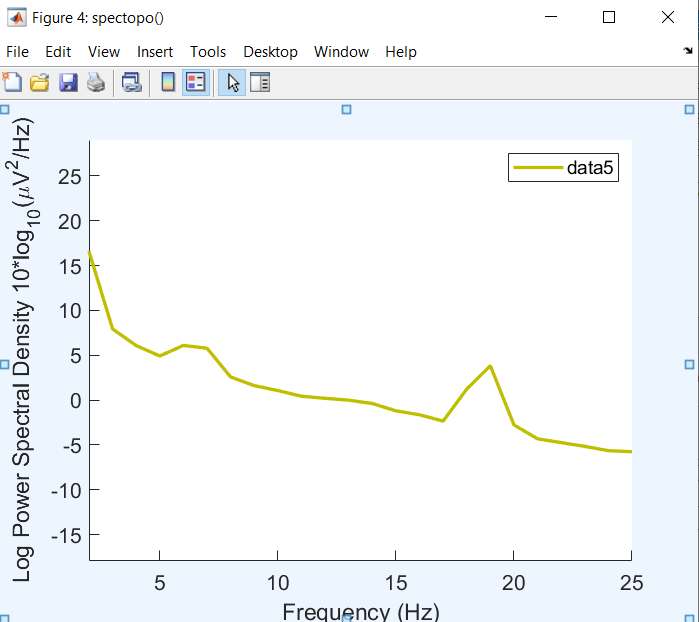

### do Step 2  :

removing artifacts and non-brain components

First of all we dont need data before 14s , so we are going to delete it .

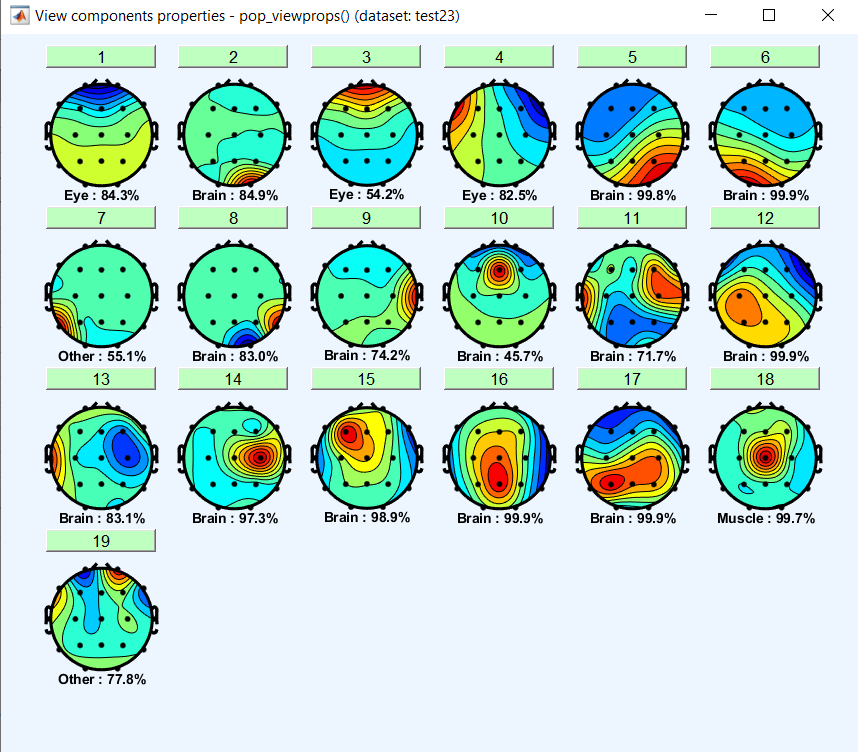

Now we are going to remove non-brain components :

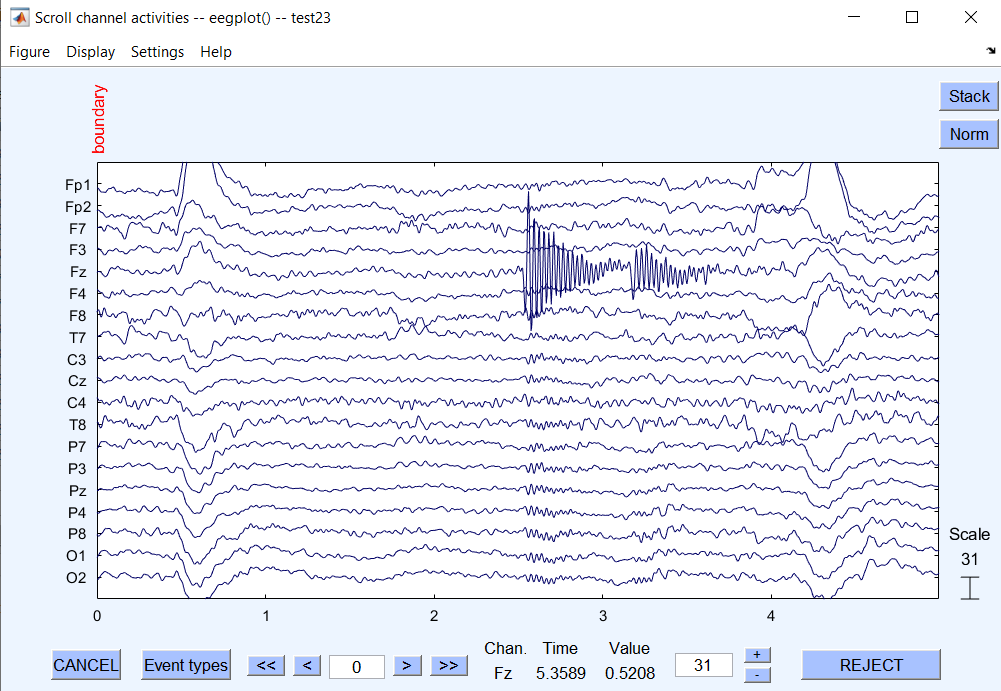

### do Step 3  :

Epoch the data of each subject.

We are going to define a function and use to epoch the data .

Also we have removed data befor 14s .

ep2 = epoch((EEG.data)'); %% function code is in functions part ;

#### do Step 4 :

removing noisy trial is our next step .

We are going to use the code in the project file .

noisy_trials2 = [] ;

for i = 1:19

    vr = sum ( nanstd (ep2(i,:,:) ,[] ,2) .^2 ,2) ;
    noisy = find ( abs ( zscore ( vr )) > 3.5) ;
    noisy_trials2 = [noisy_trials2 , noisy'] ;

end

noisy_trials2 = unique(noisy_trials2) ;

#### do Step 5 :

subsampling and creating struct .

fepoch2 = ep2 ( [1,5,10,15] , : , : ) ;

s2 = struct( 'epoch', {fepoch2} , 'odor' , {normal(11).odor} , 'niosy' , {noisy_trials2} ) ;

# 3.4    Phase Locking Value (PLV)

## 1.

Phase synchronization refers to the phenomenon where the neural oscillations of different brain regions become coordinated and align their phase angles. It indicates that these regions are actively communicating and working together to perform a specific cognitive or perceptual function.

From a functional point of view, phase synchronization plays a crucial role in various cognitive processes, including attention, perception, memory, and information integration. When different brain regions synchronize their oscillatory activity, it suggests that they are engaged in coordinated processing and are likely involved in the same neural network or functional pathway.

Phase synchronization is thought to facilitate efficient information transfer and integration across brain regions. By aligning their phase angles, neurons in different regions can establish precise timing relationships, enabling the effective exchange and integration of information. This synchronization allows for the binding of information from different sources and the coordination of distributed neural processes required for complex cognitive tasks.

Furthermore, phase synchronization can reflect the dynamic organization and coordination of brain networks. Different cognitive tasks may require the recruitment of different brain regions and the synchronization of their activity in specific frequency bands. Changes in phase synchronization patterns can indicate the reconfiguration of functional networks during different cognitive states or the emergence of new network dynamics associated with specific mental processes.

Overall, phase synchronization provides valuable insights into the functional connectivity and coordination of neural activity in the brain. Understanding the patterns of phase synchronization can help unravel the mechanisms underlying cognitive functions and their alterations in neurological and psychiatric disorders.

## 2.

The Phase Locking Value (PLV) is a measure used to quantify the phase synchronization or phase coherence between two or more time series signals. It provides a numerical value that indicates the degree of phase locking or synchronization between the signals.

To calculate the PLV, several mathematical tools and techniques are employed:

- Analytic Signal: The first step involves transforming the time series signals into complex-valued analytic signals. This is typically achieved using the Hilbert transform. The analytic signal preserves the original amplitude information while extracting the phase component of the signal.

- Instantaneous Phase: After obtaining the analytic signals, the instantaneous phase is computed for each signal at each time point. The phase represents the angle or position of the complex signal in the complex plane and is often calculated using functions like the arctan or atan2.

- Phase Difference: The phase difference between the signals is then calculated. This is achieved by subtracting the phase of one signal from the phase of the other signal at each time point. The phase difference represents the phase relationship between the signals.

- Absolute Value and Averaging: The absolute value of the complex exponential of the phase difference is taken to eliminate negative values and retain the magnitude of the phase difference. The resulting values are then averaged over a specified period to obtain the PLV.

Mathematically, the PLV can be defined as follows:

$\textrm{PLV}=\frac{|\Sigma \left(e^{i\Delta \phi } \right)|}{N}$ ;

Where:

- N represents the number of time points or samples over which the averaging is performed.

- Σ denotes the sum of the complex exponentials of the phase differences.

- Δϕ represents the phase difference between the signals at each time point.

- i is the imaginary unit.

By averaging the complex exponentials, the PLV provides a measure of the average phase locking or synchronization between the signals.

It's important to note that variations and extensions of the PLV calculation exist, depending on specific research contexts and requirements. For example, different approaches to averaging, phase unwrapping, or pre-processing techniques may be employed to enhance the accuracy and reliability of the PLV calculation in different applications.

## 3.

Function code is in Functions part .

# 4.    Results

# 4.1 , 4.2 , 4.3 

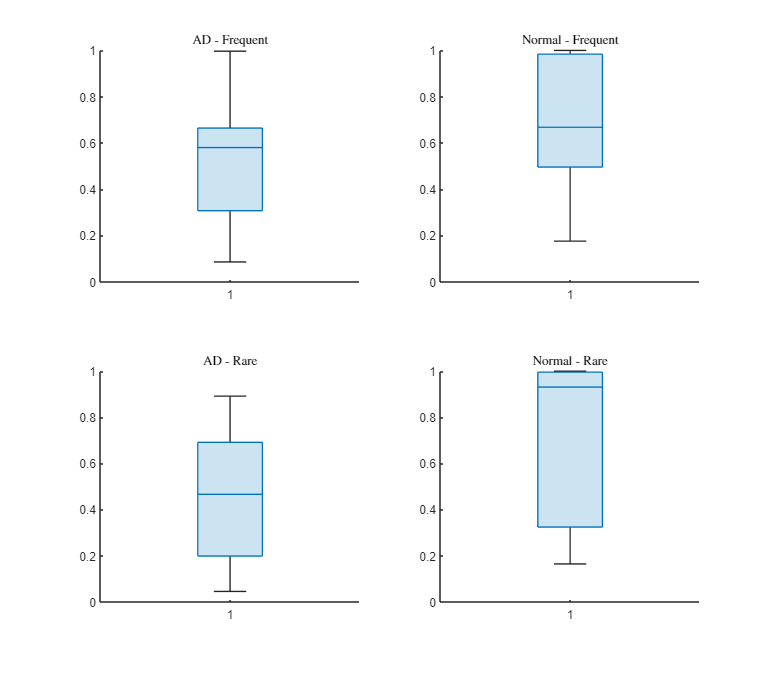

clear ;

load('AD.mat') ;
load('Normal.mat')
warning('off') ;

ADfrodor = zeros(1 , 13) ;
ADraodor = zeros(1 , 13) ;


for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = bandpass(meanepochfr(ADepoch , ADodor),[35 40],200) ;
    ADfrodor(i) = PLV( temp1(2,:) , temp1(3,:) ) ;
    temp2 = bandpass(meanepochra(ADepoch , ADodor),[35 40],200); 
    ADraodor(i) = PLV( temp2(2,:) , temp2(3,:) ) ;

end

Normfrodor = zeros(1 , 15) ;
Normraodor = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = bandpass(meanepochfr(Normepoch , Normodor), [35,40] ,200) ;
    Normfrodor(i) = PLV( temp1(2,:) , temp1(3,:) ) ;
    temp2 = bandpass(meanepochra(Normepoch , Normodor),[35,40],200) ; 
    Normraodor(i) = PLV( temp2(2,:) , temp2(3,:) ) ;

end

f1 = figure ;
figure(f1) ;
f1.Position = [0,0,800,700] ;
subplot(2,2,1)
boxchart(ADfrodor) ;
title('AD - Frequent' , 'Interpreter','latex') ;
subplot(2,2,2) ;
boxchart(Normfrodor);
title('Normal - Frequent' , 'Interpreter','latex') ;
subplot(2,2,3);
boxchart(ADraodor);
title('AD - Rare' , 'Interpreter','latex') ;
subplot(2,2,4) ;
boxchart(Normraodor);
title('Normal - Rare' , 'Interpreter','latex') ;

f2 = figure ;
figure(f2) ;
f2.Position = [0,0,800,700] ;

x = -3:.05:3 ;


ADfrodorpd = fitdist(ADfrodor','Normal')

ADfrodorpd =   NormalDistribution

  Normal distribution
       mu = 0.522272   [0.351932, 0.692612]
    sigma = 0.281883   [0.202134, 0.465314]


ADraodorpd = fitdist(ADraodor','Normal')

ADraodorpd =   NormalDistribution

  Normal distribution
       mu = 0.456478   [0.278862, 0.634095]
    sigma = 0.293924   [0.210769, 0.485191]


Normfrodorpd = fitdist(Normfrodor','Normal')

Normfrodorpd =   NormalDistribution

  Normal distribution
       mu = 0.709308   [0.551438, 0.867179]
    sigma = 0.285077   [0.208713, 0.449595]


Normraodorpd = fitdist(Normraodor','Normal')

Normraodorpd =   NormalDistribution

  Normal distribution
       mu = 0.709443   [0.519728, 0.899158]
    sigma = 0.342581   [0.250813, 0.540285]


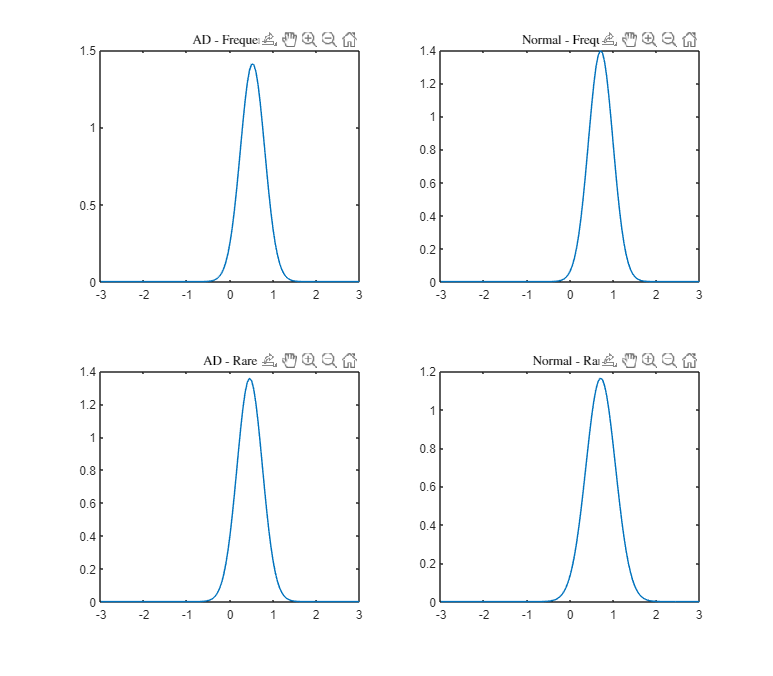

subplot(2,2,1)
y = normpdf(x,ADfrodorpd.mu,ADfrodorpd.sigma);
plot(x,y);
title('AD - Frequent' , 'Interpreter','latex') ;
subplot(2,2,2);
y = normpdf(x,Normfrodorpd.mu,Normfrodorpd.sigma);
plot(x,y);
title('Normal - Frequent' , 'Interpreter','latex') ;
subplot(2,2,3);
y = normpdf(x,ADraodorpd.mu,ADraodorpd.sigma);
plot(x,y);
title('AD - Rare' , 'Interpreter','latex') ;
subplot(2,2,4);
y = normpdf(x,Normraodorpd.mu,Normraodorpd.sigma);
plot(x,y);
title('Normal - Rare' , 'Interpreter','latex') ;

Hypothesis :

H0  : $\mu 1-\mu 2=0$

H1 : $\;\mu 1-\mu 2\;\not= 0$

[Hypothesisfr,pvaluefr] = ttest2(Normfrodor,ADfrodor)

Hypothesisfr = 0

pvaluefr = 0.0936

[Hypothesisra,pvaluera] = ttest2(Normraodor,ADraodor)

Hypothesisra = 1

pvaluera = 0.0476

With  significance level of 95 % we can say that there is a diffrent between Normal and AD gorup PLV for rare odor .

# 4.4

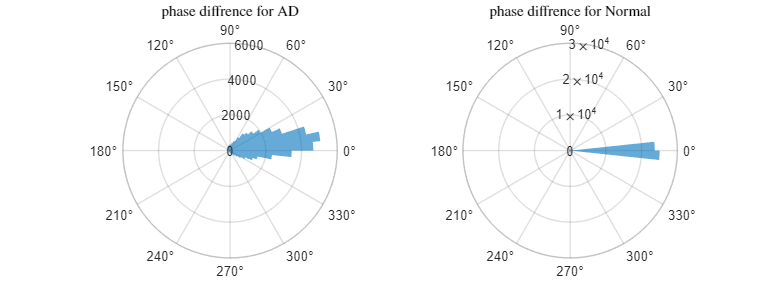

clear ;

load('AD.mat') ;
load('Normal.mat')
warning('off') ;

randsub1epoch = AD(5).epoch ; %% subject 5 is our random subject for AD group
randsub1odor = AD(5).odor; 

pdsAD = phasediff(randsub1epoch,randsub1odor);


randsub2epoch = normal(5).epoch ; %% subject 5 is our random subject for Normal group
randsub2odor = normal(5).odor; 

pdsNorm = phasediff(randsub2epoch,randsub2odor);


f3 = figure ;
figure(f3) ;
f3.Position = [0,0,800,300];

subplot(1,2,1);
polarhistogram(pdsAD,60,'EdgeColor','none');
title('phase diffrence for AD' , 'Interpreter','latex');
subplot(1,2,2);
polarhistogram(pdsNorm,60,'EdgeColor','none');
title('phase diffrence for Normal' , 'Interpreter','latex');
grADplvs = zeros(1 , 13) ;



for i = 1:13

    grADplvs(i) = mean( phasediff( AD(i).epoch , AD(i).odor) );

end

grNormplvs = zeros(1 , 15) ;


for i = 1:15

    grNormplvs(i) = mean( phasediff( normal(i).epoch , normal(i).odor) );

end

f4 = figure ;
figure(f4) ;
f4.Position = [0,0,800,300];

subplot(1,2,1) ;
plot(grADplvs);
title('Mean value of Subject - AD (frequent odor)' , 'Interpreter','latex') ;
ylim([0 0.2]);
subplot(1,2,2) ;
plot(grNormplvs);
title('Mean value of Subject - Normal (frequent odor)' , 'Interpreter','latex') ;
ylim([0 0.2]);

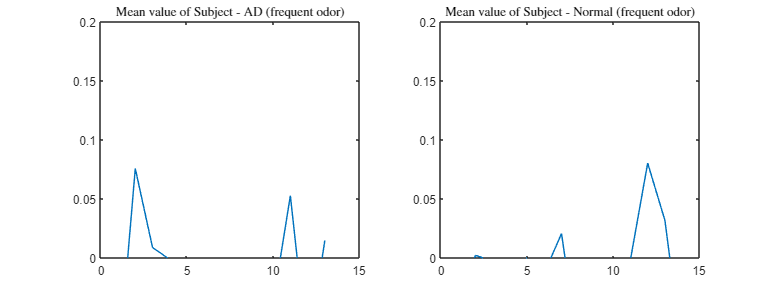

clear ;

load('AD.mat') ;

load('Normal.mat')
warning('off') ;

f = figure ;
figure(f) ;
f.Position = [0,0,800,600] ;

[Data1ad , Data2ad] = CalallPLVs(AD) ;
[Data1norm , Data2norm] = CalallPLVs(normal) ;

yvalues = {'Fp1','Fz ','Cz','Pz'};
xvalues = {'Fp1','Fz ','Cz','Pz'};

subplot(2,2,1);
heatmap(xvalues,yvalues,Data1ad);
title('AD - Frequent') ;
subplot(2,2,2);
heatmap(xvalues,yvalues,Data1norm);
title('Normal - Frequent') ;
subplot(2,2,3);
heatmap(xvalues,yvalues,Data2ad);
title('AD - Rare') ;
subplot(2,2,4);
heatmap(xvalues,yvalues,Data2norm);
title('Normal - Rare') ;

- As we can see , similar to Fz & Cz there is significance diffrence between Fz & Pz .

Now we are going to test if Fz and Pz are actually diffrent for frequent odor and rare odor .

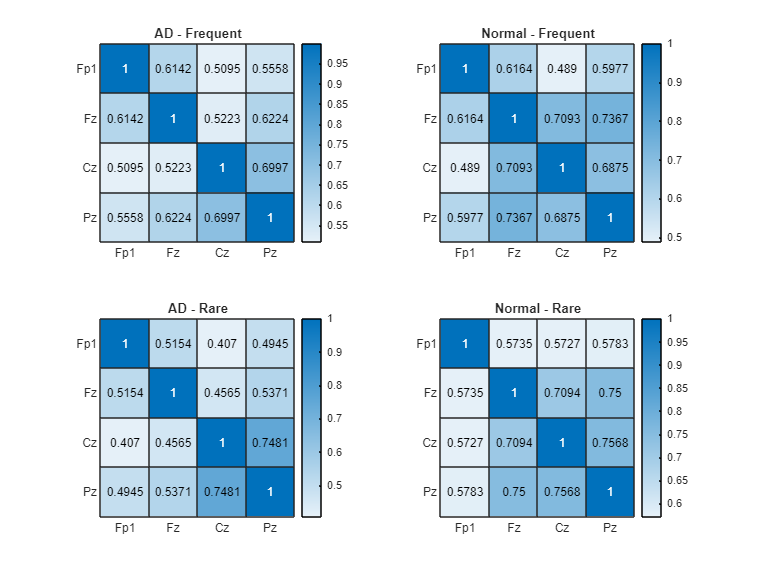

ADfrodortest = zeros(1 , 13) ;
ADraodortest = zeros(1 , 13) ;
    
    

for i = 1:13
    
ADepoch = AD(i).epoch ;
ADodor = AD(i).odor;
        
    
temp1 = bandpass( meanepochfr(ADepoch , ADodor), [35 40] , 200) ;
ADfrodortest(i) = PLV( temp1(2,:) , temp1(4,:) ) ;
temp2 = bandpass( meanepochra(ADepoch , ADodor),[35 40],200); 
ADraodortest(i) = PLV( temp2(2,:) , temp2(4,:) ) ;
    
end

Normfrodortest = zeros(1 , 15) ;
Normraodortest = zeros(1 , 15) ;
    
    
for i = 1:15
    
Normepoch = normal(i).epoch ;
Normodor = normal(i).odor;
        
temp1 = bandpass(meanepochfr(Normepoch , Normodor),[35,40],200) ;
Normfrodortest(i) = PLV( temp1(2,:) , temp1(4,:)) ;
temp2 = bandpass(meanepochra(Normepoch , Normodor),[35,40],200) ; 
Normraodortest(i) = PLV( temp2(2,:) , temp2(4,:)) ;
    
end

[hypothesisfrequentodor , pvaluefrequentodor] = ttest2(ADfrodortest,Normfrodortest)
[hypothesisrareodor , pvaluerareodor] = ttest2(ADraodortest , Normraodortest)

- With significance level of  93% We can say that there is a diffrence between Normal and AD PVL(Pz,Fz) for rare odor . 

- With significance level of  85% We can say that there is a diffrence between Normal and AD PVL(Pz,Fz) for frequent odor .

MCI (Mild Cognitive Impairment) and AD (Alzheimer's disease) are related but distinct conditions. MCI is a condition characterized by mild cognitive decline that is greater than what is expected for normal aging but does not significantly interfere with daily activities. On the other hand, AD is a progressive neurodegenerative disease that causes severe memory loss, cognitive decline, and impairment in daily functioning.

While MCI can be considered a precursor or an early stage of AD, not all individuals with MCI will develop AD. Some individuals with MCI may remain stable or even improve their cognitive abilities over time, while others may progress to develop other forms of dementia or remain with stable MCI. It is estimated that approximately 10-15% of individuals with MCI progress to AD each year, but the conversion rate can vary depending on various factors.

The causes of MCI are not fully understood, and it can have multiple underlying causes. Some common causes and risk factors associated with MCI include:

- Age: Advanced age is the most significant risk factor for MCI. As individuals grow older, the risk of experiencing cognitive decline increases.

- Alzheimer's pathology: In many cases, MCI is associated with early stages of Alzheimer's disease pathology, such as the accumulation of beta-amyloid plaques and tau tangles in the brain. However, not all individuals with MCI have Alzheimer's pathology, and other factors can contribute to cognitive impairment.

- Vascular disease: Conditions that affect blood vessels, such as hypertension, diabetes, or a history of strokes, can increase the risk of developing MCI.

- Genetics: Certain genetic factors, such as the presence of the APOE ε4 allele, are associated with an increased risk of both MCI and AD. However, having these genetic factors does not guarantee that an individual will develop MCI or AD.

- Lifestyle factors: Unhealthy lifestyle choices, such as a sedentary lifestyle, poor diet, smoking, or excessive alcohol consumption, can contribute to cognitive decline and increase the risk of developing MCI.

It's important to note that MCI can have various causes, and it's not always possible to determine the exact cause in every individual. Proper evaluation and diagnosis by healthcare professionals are crucial for understanding the underlying cause and determining appropriate management strategies for individuals with MCI.

clear ;

hypothesisfrequentodor = 0

pvaluefrequentodor = 0.2468

hypothesisrareodor = 0

pvaluerareodor = 0.0619

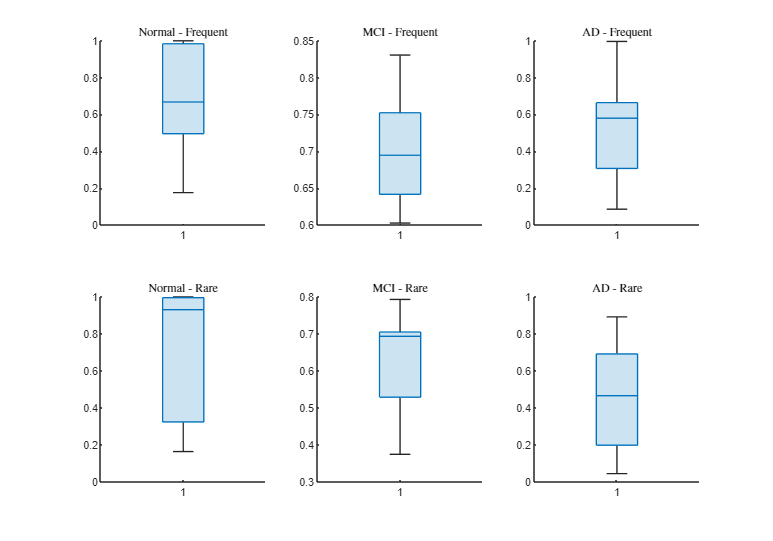

load('AD.mat');
load('MCI.mat');
load('Normal.mat');

warning('off') ;

ADfrodor = zeros(1 , 13) ;
ADraodor = zeros(1 , 13) ;


for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = bandpass(meanepochfr(ADepoch , ADodor),[35 40],200) ;
    ADfrodor(i) = PLV( temp1(2,:) , temp1(3,:) ) ;
    temp2 = bandpass(meanepochra(ADepoch , ADodor),[35 40],200); 
    ADraodor(i) = PLV( temp2(2,:) , temp2(3,:) ) ;

end

Normfrodor = zeros(1 , 15) ;
Normraodor = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = bandpass(meanepochfr(Normepoch , Normodor), [35,40] ,200) ;
    Normfrodor(i) = PLV( temp1(2,:) , temp1(3,:) ) ;
    temp2 = bandpass(meanepochra(Normepoch , Normodor),[35,40],200) ; 
    Normraodor(i) = PLV( temp2(2,:) , temp2(3,:) ) ;

end

MCIfrodor = zeros(1 , 7) ;
MCIraodor = zeros(1 , 7) ;

for i = 1:7

    MCIepoch = MCI(i).epoch ;
    MCIodor = MCI(i).odor;
    
    temp1 = bandpass( meanepochfr(MCIepoch , MCIodor) , [35,40] , 200 ) ;
    MCIfrodor(i) = PLV( temp1(2,:) , temp1(3,:) ) ;
    temp2 = bandpass(meanepochra(MCIepoch , MCIodor),[35,40],200) ;
    MCIraodor(i) = PLV( temp2(2,:) , temp2(3,:) ) ;

end

f1 = figure;
f1.Position = [0 0 1000 700];
subplot(2,3,1) ;
boxchart(Normfrodor);
title('Normal - Frequent' , 'Interpreter','latex');
subplot(2,3,2) ;
boxchart(MCIfrodor);
title('MCI - Frequent' , 'Interpreter','latex');
subplot(2,3,3) ;
boxchart(ADfrodor);
title('AD - Frequent' , 'Interpreter','latex');
subplot(2,3,4) ;
boxchart(Normraodor);
title('Normal - Rare' , 'Interpreter','latex');
subplot(2,3,5) ;
boxchart(MCIraodor);
title('MCI - Rare' , 'Interpreter','latex');
subplot(2,3,6) ;
boxchart(ADraodor);
title('AD - Rare' , 'Interpreter','latex');
MCIfrodorpd = fitdist(MCIfrodor','Normal')
MCIraodorpd = fitdist(MCIraodor','Normal')
f2 = figure;
figure(f2);
f2.Position = [0,0,800,250]

x = -3 : 0.05 : 3 ;

subplot(1,2,1)
y = normpdf(x,MCIfrodorpd.mu,MCIfrodorpd.sigma);

plot(x,y);

MCIfrodorpd =   NormalDistribution

  Normal distribution
       mu =  0.703822   [0.631623, 0.776022]
    sigma = 0.0780666   [0.0503056, 0.171908]


title('MCI - Frequent' , 'Interpreter','latex');

MCIraodorpd =   NormalDistribution

  Normal distribution
       mu = 0.620096   [0.487131, 0.753061]
    sigma =  0.14377   [0.0926444, 0.316591]


subplot(1,2,2)
y = normpdf(x,MCIraodorpd.mu,MCIraodorpd.sigma);
plot(x,y);

f2 =   Figure (109) with properties:

      Number: 109
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 250]
       Units: 'pixels'

  Show all properties


title('MCI - Rare' , 'Interpreter', ' latex') ;
ylim([0 6]);
[HfrNormVsMCI,pfrNormVsMCI] = ttest2(Normfrodor,MCIfrodor)
[HraNormVsMCI,praNormVsMCI] = ttest2(Normraodor,MCIraodor)
[HfrNormVsAD,pfrNormVsAD] = ttest2(Normfrodor,ADfrodor)
[HraNormVsAD,praNormVsAD] = ttest2(Normraodor,ADraodor)
[HfrADVsMCI,pfrADVsMCI] = ttest2(ADfrodor,MCIfrodor)
[HraADVsMCI,praADVsMCI] = ttest2(ADraodor,MCIraodor)

# 5.1 Mild Cognitive Impairment (MCI) 

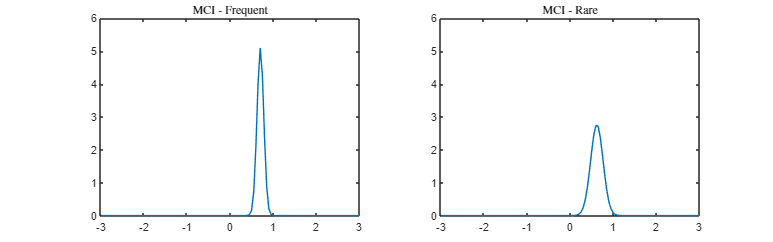

close all ;

load('AD.mat')
load('MCI.mat')

load('Normal.mat')

HfrNormVsMCI = 0

pfrNormVsMCI = 0.9610

HraNormVsMCI = 0

praNormVsMCI = 0.5189

randsub1epoch = AD(5).epoch ;

HfrNormVsAD = 0

pfrNormVsAD = 0.0936

randsub1odor = AD(5).odor; 

HraNormVsAD = 1

praNormVsAD = 0.0476

HfrADVsMCI = 0

pfrADVsMCI = 0.1160

plvsAD = phasediff(randsub1epoch,randsub1odor);

HraADVsMCI = 0

praADVsMCI = 0.1862



randsub2epoch = normal(5).epoch ;
randsub2odor = normal(5).odor; 

plvsNorm = phasediff(randsub2epoch,randsub2odor);

randsub3epoch = MCI(5).epoch ;
randsub3odor = MCI(5).odor; 

plvsMCI = phasediff(randsub3epoch,randsub3odor);


polarhistogram(plvsNorm,60 , 'EdgeColor','none') ;
polarhistogram(plvsMCI,60,'EdgeColor','none');
polarhistogram(plvsAD,60,'EdgeColor','none');
grMCIplvs = zeros(1 , 7) ;


for i = 1:7

    grMCIplvs(i) = mean( phasediff( MCI(i).epoch , MCI(i).odor) );

end

plot(grMCIplvs) ;

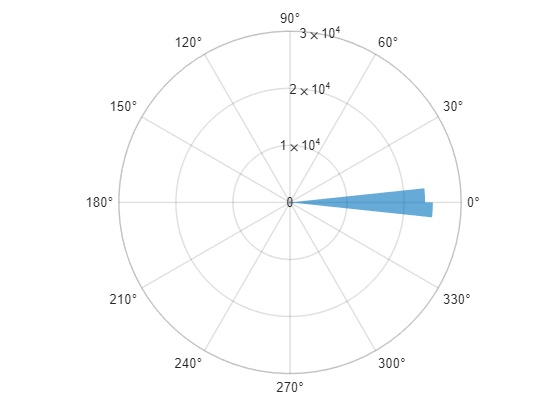

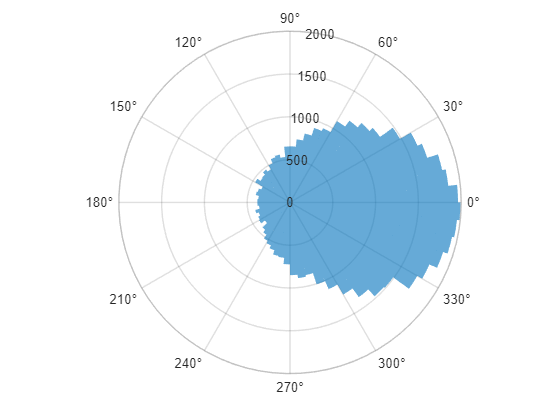

clear ;

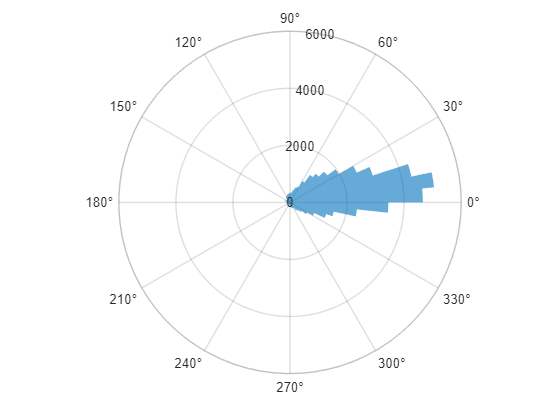

load('AD.mat') ;

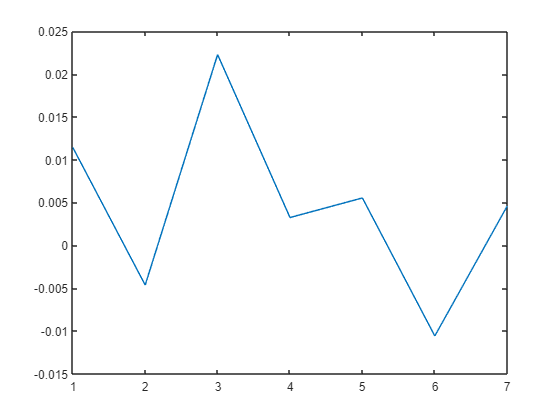

load('Normal.mat');
load('MCI.mat');
warning('off') ;

f = figure ;
figure(f) ;
f.Position = [0,0,800,800] ;

[Data1ad , Data2ad] = CalallPLVs(AD) ;
[Data1norm , Data2norm] = CalallPLVs(normal) ;

[Data1mci , Data2mci] = CalallPLVs(MCI) ;

yvalues = {'Fp1','Fz ','Cz','Pz'};
xvalues = {'Fp1','Fz ','Cz','Pz'};

subplot(3,2,1);
heatmap(xvalues,yvalues,Data1ad);
title('AD - Frequent') ;

subplot(3,2,3);
heatmap(xvalues,yvalues,Data1norm);
title('Normal - Frequent') ;

subplot(3,2,5);
heatmap(xvalues,yvalues,Data1mci);
title('MCI - Frequent') ;

subplot(3,2,2);
heatmap(xvalues,yvalues,Data2ad);
title('AD - Rare') ;

subplot(3,2,4);
heatmap(xvalues,yvalues,Data2norm);
title('Normal - Rare') ;

subplot(3,2,6);
heatmap(xvalues,yvalues,Data2mci);
title('MCI - Rare') ;

# 5.2 Phase-Amplitude Coupling (PAC) 

PAC stands for Phase-Amplitude Coupling, and it is a concept used in neuroscience to describe the interactions between different brain rhythms. It refers to the synchronization between the phase of one brain oscillation (such as theta or alpha waves) and the amplitude of another oscillation (such as gamma waves). This phenomenon reflects the coordination and communication between different brain regions, which is thought to be important for various cognitive processes.

Here are two common measures used to study PAC:

- Modulation Index (MI): The modulation index quantifies the strength of the coupling between two brain oscillations. It is calculated by comparing the amplitude distribution of the higher-frequency oscillation (e.g., gamma) at different phases of the lower-frequency oscillation (e.g., theta). A higher MI value indicates a stronger coupling between the two oscillations, suggesting that the phase of the lower-frequency rhythm influences the amplitude of the higher-frequency rhythm more significantly.

- Coupling Strength: Coupling Strength is another PAC measure used to assess the degree of coupling between phase and amplitude oscillations. It evaluates the statistical association or correlation between the phase and amplitude time series. Coupling strength measures how well the phase of low-frequency oscillations predicts the amplitude of high-frequency oscillations. A higher coupling strength suggests a stronger relationship between the two frequency bands, indicating a more coordinated interaction between brain regions.

Researchers use PAC measures to investigate the functional connectivity between brain regions and understand how different rhythms interact to support cognitive functions. For example, PAC has been associated with memory processes, attention, and sensory perception. Abnormalities in PAC have also been observed in certain neurological and psychiatric conditions, such as epilepsy, schizophrenia, and Alzheimer's disease. By studying PAC, researchers aim to gain insights into the underlying mechanisms of brain function and dysfunction, potentially leading to new diagnostic and therapeutic approaches for brain-related disorders.

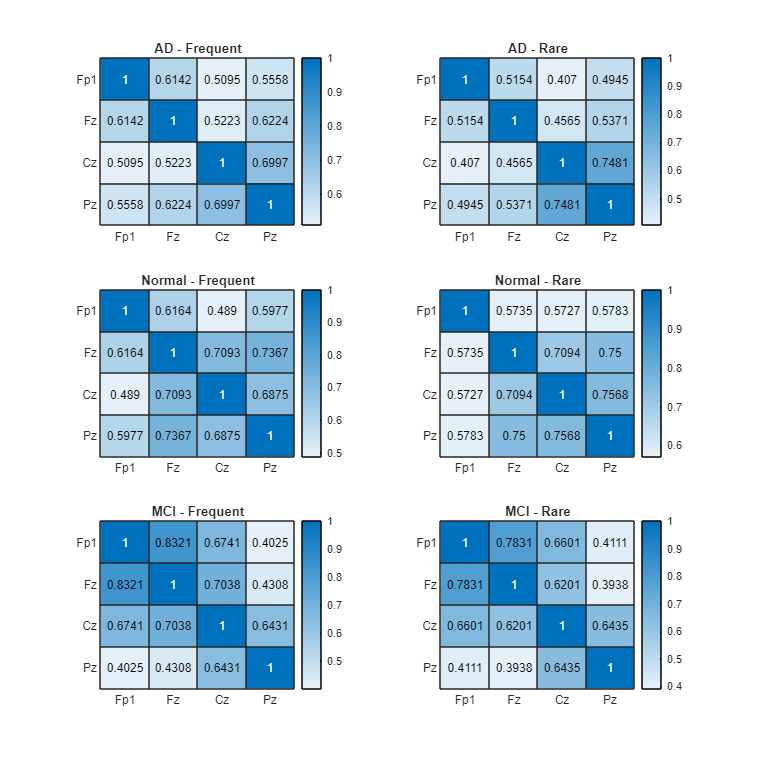

clear ;

load('AD.mat');
load('MCI.mat');
load('Normal.mat');

warning('off') ;

ADfrodor1 = zeros(1 , 13) ;
ADraodor1 = zeros(1 , 13) ;

f = figure ;
figure(f);



for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = meanepochfr(ADepoch , ADodor) ;
    ADfrodor1(i) = MVL( temp1(1,:) ) ;
    temp2 = meanepochra(ADepoch , ADodor); 
    ADraodor1(i) = MVL( temp2(1,:) ) ;

end

Normfrodor1 = zeros(1 , 15) ;
Normraodor1 = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = meanepochfr(Normepoch , Normodor) ;
    Normfrodor1(i) = MVL( temp1(1,:) ) ;
    temp2 = meanepochra(Normepoch , Normodor) ; 
    Normraodor1(i) = MVL( temp2(1,:) ) ;

end

ADfrodor2 = zeros(1 , 13) ;
ADraodor2 = zeros(1 , 13) ;


for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = meanepochfr(ADepoch , ADodor) ;
    ADfrodor2(i) = MVL( temp1(2,:) ) ;
    temp2 = meanepochra(ADepoch , ADodor); 
    ADraodor2(i) = MVL( temp2(2,:) ) ;

end

Normfrodor2 = zeros(1 , 15) ;
Normraodor2 = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = meanepochfr(Normepoch , Normodor) ;
    Normfrodor2(i) = MVL( temp1(2,:) ) ;
    temp2 = meanepochra(Normepoch , Normodor) ; 
    Normraodor2(i) = MVL( temp2(2,:) ) ;

end


ADfrodor3 = zeros(1 , 13) ;
ADraodor3 = zeros(1 , 13) ;


for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = meanepochfr(ADepoch , ADodor) ;
    ADfrodor3(i) = MVL( temp1(3,:) ) ;
    temp2 = meanepochra(ADepoch , ADodor); 
    ADraodor3(i) = MVL( temp2(3,:) ) ;

end

Normfrodor3 = zeros(1 , 15) ;
Normraodor3 = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = meanepochfr(Normepoch , Normodor) ;
    Normfrodor3(i) = MVL( temp1(3,:) ) ;
    temp2 = meanepochra(Normepoch , Normodor) ; 
    Normraodor3(i) = MVL( temp2(3,:) ) ;

end


ADfrodor4 = zeros(1 , 13) ;
ADraodor4 = zeros(1 , 13) ;


for i = 1:13

    ADepoch = AD(i).epoch ;
    ADodor = AD(i).odor;
    

    temp1 = meanepochfr(ADepoch , ADodor) ;
    ADfrodor4(i) = MVL( temp1(2,:) ) ;
    temp2 = meanepochra(ADepoch , ADodor); 
    ADraodor4(i) = MVL( temp2(2,:) ) ;

end

Normfrodor4 = zeros(1 , 15) ;
Normraodor4 = zeros(1 , 15) ;


for i = 1:15

    Normepoch = normal(i).epoch ;
    Normodor = normal(i).odor;
    
    temp1 = meanepochfr(Normepoch , Normodor) ;
    Normfrodor4(i) = MVL( temp1(2,:) ) ;
    temp2 = meanepochra(Normepoch , Normodor) ; 
    Normraodor4(i) = MVL( temp2(2,:) ) ;

end


DataMVLs = [mean(ADfrodor1)  mean(Normfrodor1)  mean(ADraodor1)  mean(Normraodor1) ;
            mean(ADfrodor2)  mean(Normfrodor2)  mean(ADraodor2)  mean(Normraodor2) ;
            mean(ADfrodor3)  mean(Normfrodor3)  mean(ADraodor3)  mean(Normraodor3) ;
            mean(ADfrodor4)  mean(Normfrodor4)  mean(ADraodor4)  mean(Normraodor4)
            ];

yvalues = {'Fp1','Fz','Cz' , 'Pz' };
xvalues = {'AD frequent','Normal frequent','AD rare','Normal rare'};

h = heatmap(xvalues,yvalues,DataMVLs);

# 6.    Conclusion

In this project we found that we can distinguish AD with using EEG signals of brain . First we get the raw data then we have to preprocess it for having less bias in future calculations .

after processing resulsts showed us that there is a significance diffrence between AD group and Normal group for EEG signals that we get form rare odors that as it was mentionod in project it was rose odor . (95% significance level)

Also for Mild cognitive impairment (MCI) that is an early stage of memory loss or other cognitive ability loss we found that wi can't significantly say that the data we gathered is different form AD and Normal (We couldn't reject null Hypothesis for both AD and Normal group ) So we can consider it as a symptom of AD .

We have higher PLVs for normal group camparing to other group Also we hawe same phase diffrence for normal group but other groups have variant phas diffrence . Also PLVs is an example of PAC metrics , so if PLVs is higher we have higher synchronization.

# Functions

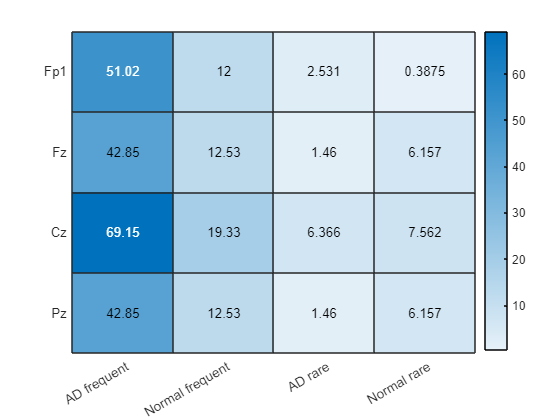

function e = epoch(s)

    e = zeros(19,600,120) ;

    for i = 1:19

        for j = 1:120
            
            temp = s ( (j*2000)-599 : (j*2000) , i) ;
            e(i,:,j) = temp ;


        end

    end

end    

function x = PLV ( f1 , f2 )

    hb1 = hilbert(f1);
    hb2 = hilbert(f2);
    n = length(hb1);
    del = zeros(1,n);

    for i = 1:n
        del(i) = exp( 1j * ( angle(hb1(i)) - angle(hb2(i)) ) ) ;
    end

    x = (1/n)*abs(sum(del));

end


function x = MVL (f)
    
    F = hilbert (f) ;
    l = length(f);
    x = abs(sum(F))/l ;

end


function x = meanepochfr( a , b )

    [~,~,x3] = size(a);
    sum = a(:,:,1) ;
    
    for i = 2:x3
    
        if b(i) == 0
            sum = sum + a(:,:,i) ; 
        end
    
    end

    x = (sum/x3) ;

end

function x = meanepochra( a , b )

    [~,~,x3] = size(a);
    sum = a(:,:,1) ;
    
    for i = 2:x3
    
        if b(i) == 1
            sum = sum + a(:,:,i) ; 
        end
    
    end

    x = (sum/x3) ;

end

function pds = phasediff( a , b )

    pds = [] ;
    
    for i = 1:length(b)
    
        if b(i) == 0
            
            f1 = hilbert(a(2,:,i)) ;
            f2 = hilbert(a(3,:,i)) ;
            pds = [pds , angle(f1) - angle(f2) ] ;
    
        end 

    end

end

function [ Data1 , Data2 ] = CalallPLVs( s )
     
     [~,subs] = size(s) ;

     fr = zeros(1 , subs) ;
     ra = zeros(1 , subs) ;

     Data1 = zeros(4,4) ;
     Data2 = zeros(4,4) ;
    
    for i = 1:4
        for j = 1:4
            for k = 1:subs
            
                epoch = s(k).epoch ;
                odor = s(k).odor;
                
            
                temp1 = bandpass( meanepochfr(epoch , odor) , [35 40] , 200) ;
                fr(k) = PLV( temp1(i,:) , temp1(j,:) ) ;
                temp2 = bandpass(meanepochra(epoch , odor),[35 40], 200 ); 
                ra(k) = PLV( temp2(i,:) , temp2(j,:) ) ;

            end

            Data1 (i , j)  = mean(fr) ;
            Data2 (i , j)  = mean(ra) ;

        end
    end

end